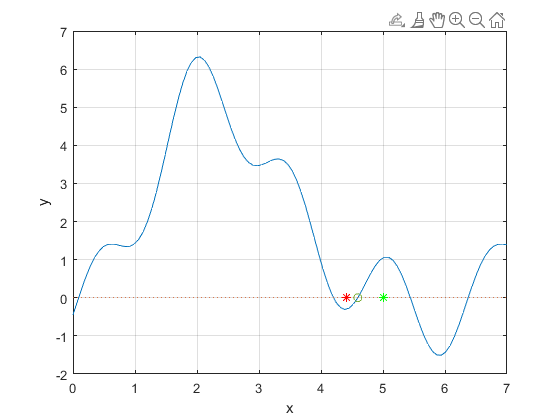

% initial params
a = 0;
b = 7;
t = linspace(a,b,100);

% identifying function
syms x
f = 1 + (1 + sin(x) - cos(x))^2 - (sin(2*x) - cos(2*x) - 0.2)^2;
df1 = diff(f);
df2 = diff(df);

plot(t, subs(f,x,t), t, 0*t, ':')
grid on
xlabel('x');
ylabel('y');

z1 = ginput(1);
a = z1(1);
z2 = ginput(1);
b = z2(1);

hold on
plot(z1(1),z1(2),'r*',z2(1),z2(2),'g*')
hold off

iter = 20;
eps = 1e-6;
xpr = (a+b)/2;
xn = 0;

for idx = 1:iter
    fpr = subs(f,x,xpr);
    dfpr = subs(df1,x,xpr);
    xn = xpr - fpr / dfpr;

    if abs(xn-xpr) < eps
        break
    end

    xpr = xn;
end

hold on
plot(xn,subs(f,x,xn),'-o')
hold off